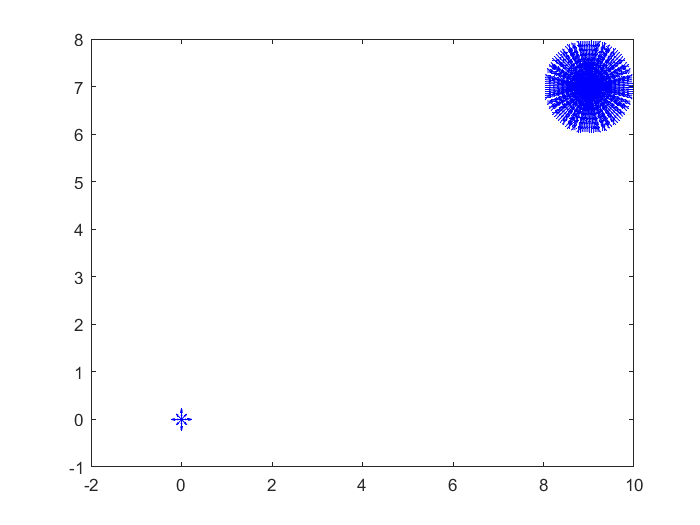

goal = [9, 7];
width = 100;
height = 100;
zeta = 10;

x = linspace(0, width, 50);
y = linspace(0, height, 50);
[X1,Y1] = meshgrid(x,y);

x0 = goal(1);
y0 = goal(2);

U1 = @(x,y) zeta*sqrt((x - goal(1)).^2 + (y - goal(2)).^2);

for r = 0:0.1:1
    % Create x and y values that span the range of the circle
    x2 = linspace(x0-r, x0+r, 50);
    y2 = linspace(y0-r, y0+r, 50);
    
    % Create a meshgrid using the x and y values
    [X_2, Y_2] = meshgrid(x2, y2);

    % Create a logical matrix that represents the points inside the circle
    logical_matrix = (X_2-x0).^2 + (Y_2-y0).^2 < r^2 ;

    % Use the logical matrix to filter the meshgrid and only keep the points inside the circle
    X2 = X_2.*logical_matrix;
    Y2 = Y_2.*logical_matrix;
    
    Z_in = U1(X2,Y2);
    
    % Calculate the gradient of the potential function
    [dx_in, dy_in] = gradient(-Z_in);
    
    quiver(X2,Y2,dx_in,dy_in,"filled","LineWidth",0.5,"Color",'b');
    hold on
    
end